# Measure Distance from Stereo Camera to a Face

Load stereo parameters.

load('webcamsSceneReconstruction.mat');

Read in the stereo pair of images.

I1 = imread('sceneReconstructionLeft.jpg');
I2 = imread('sceneReconstructionRight.jpg');

Undistort the images.

I1 = undistortImage(I1,stereoParams.CameraParameters1);
I2 = undistortImage(I2,stereoParams.CameraParameters2);

Detect a face in both images.

faceDetector = vision.CascadeObjectDetector;
face1 = faceDetector(I1);
face2 = faceDetector(I2);

Find the center of the face.

center1 = face1(1:2) + face1(3:4)/2;
center2 = face2(1:2) + face2(3:4)/2;

Compute the distance from camera 1 to the face.

point3d = triangulate(center1, center2, stereoParams);
distanceInMeters = norm(point3d)/1000;

Display the detected face and distance.

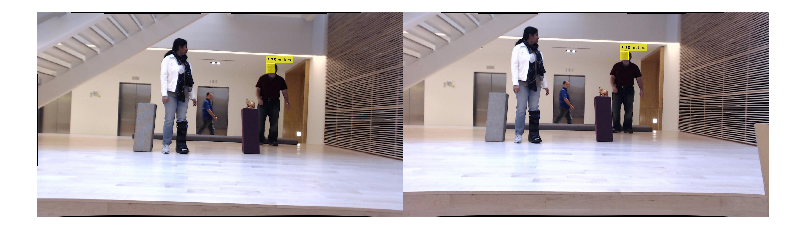

distanceAsString = sprintf('%0.2f meters', distanceInMeters);
I1 = insertObjectAnnotation(I1,'rectangle',face1,distanceAsString,'FontSize',18);
I2 = insertObjectAnnotation(I2,'rectangle',face2, distanceAsString,'FontSize',18);
I1 = insertShape(I1,'filled-rectangle',face1);
I2 = insertShape(I2,'filled-rectangle',face2);
 
imshowpair(I1, I2, 'montage');

*Copyright 2012 The MathWorks, Inc.*